# Cruise control: state-space 

## System equation

m = 1000;
b = 50;

A = -b/m;
B = 1/m;
C = 1;
D = 0;
sys = ss(A, B, C, D); % open loop transfer function

## Requirement

- Rise time < 5 s

- Overshoot < 10%

- Steady-state error < 2%

The system is a first-order system, so there is no overshoot. We only needs to care about rise time and steady state error. Based on the rise time, we need to place the roots on the left of -0.8

## Design

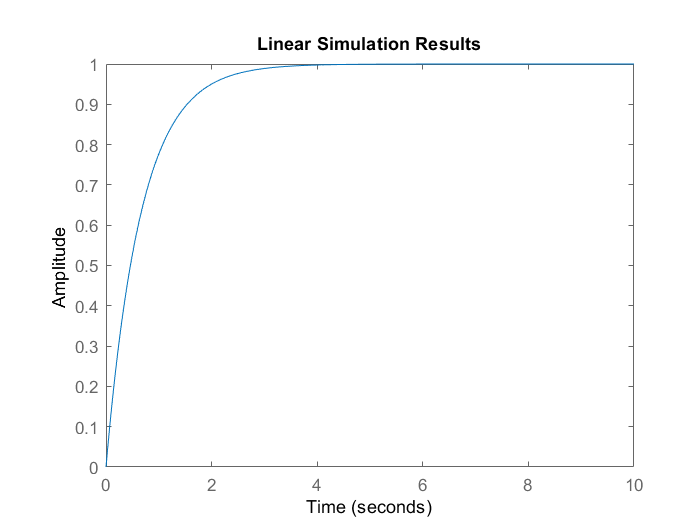

K = place(A, B, -1.5);
sys_cl = feedback(sys, K); % close-loop transfer function
N = dcgain(sys_cl); % reference rescaling

t = 0: 0.01: 10;
u = ones(size(t));
x0 = 0;
lsim(sys_cl, u/N, t);
axis([0 10 0 1]);